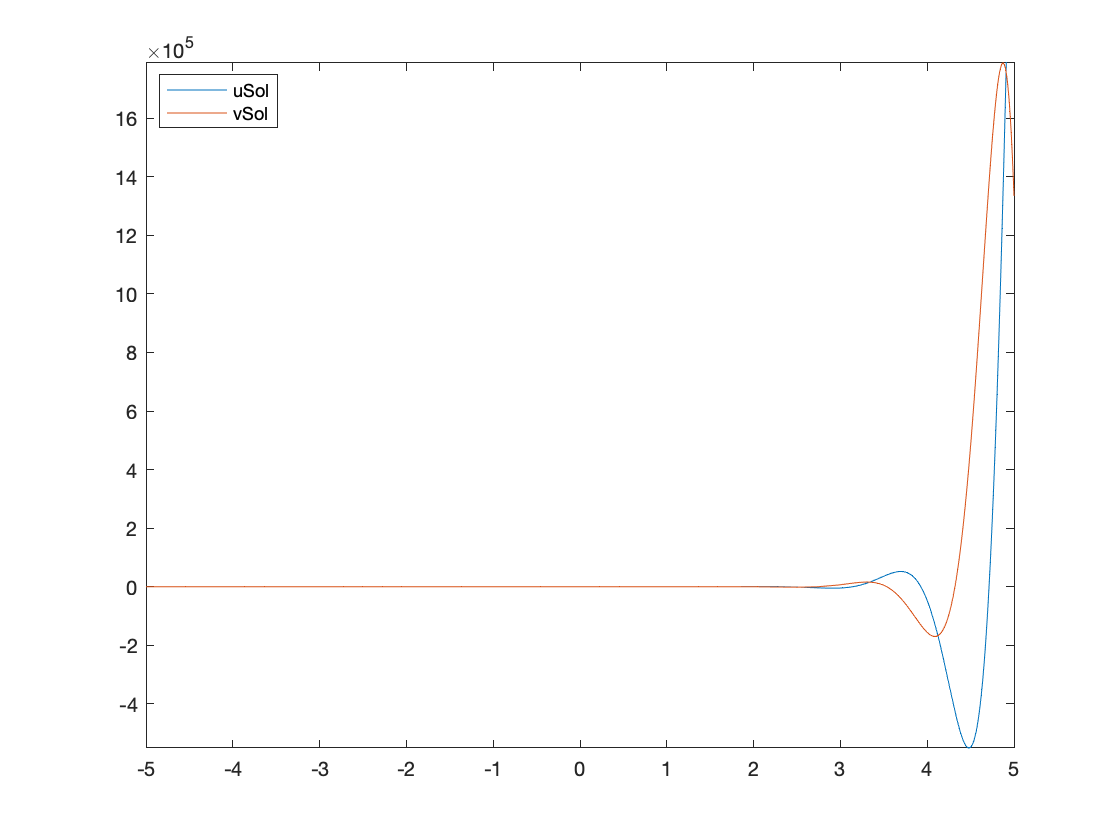







syms u(t) v(t)

strF = 3*u + 4*v;
strG = -4*u + 3*v;

ode1 = diff(u) == strF;
ode2 = diff(v) == strG;
cond1 = u(0) == 0;
cond2 = v(0) == 1;

odes = [ode1; ode2];
conds = [cond1; cond2];

t = 1:1:10;

[uSol, vSol] = dsolve(odes, conds);

fplot(uSol);
hold on;
fplot(vSol);
legend('uSol', 'vSol', 'Location', 'best');